## Experimental Data

**Author:** Surabhi Joshi

## **Summary**

This script reads in some experimental data and performs exploratory initial statistical analysis to understand how each condition affects the metabolomics before running DFA. 

% download the experimental data and create two tables, one for each
% cancer cell line TU8902 and HCT116.
experimental_data_TU8902 = readtable('Barb Nelson Pos Table-20180410 - HL.xlsx', ...
'Sheet', 'TU8902');
experimental_data_HCT116 = readtable('Barb Nelson Pos Table-20180410 - HL.xlsx', ... 
 'Sheet',"HCT116");
% delete row 2 and column 2 from both tables
experimental_data_TU8902.transition = [];
experimental_data_HCT116.transition = [];

%download metabolomics and clusterring data
metabolomics = readtable('Barb Nelson Pos Table-20180410 - HL.xlsx', ... 
    'Sheet', 'Clustering');
metabolomics(1,:) = [];
metabolomics = table2array(metabolomics);

%have a categorical array of all the conditions present
all_conditions = ["shNT no dox"; "shNT 2d dox"; "shNT 4d dox"; "shGOT1 no dox"; "shGOT1 2d dox"; "shGOT1 4d dox"; "shNT no dox media"; "shNT 2d dox media"; "shNT 4d dox media"; "shGOT1 no dox media"; "shGOT1 2d dox media"; "shGOT1 4d dox media"];
got1_conditions = ["shGOT1 no dox"; "shGOT1 2d dox"; "shGOT1 4d dox"; "shGOT1 no dox media"; "shGOT1 2d dox media"; "shGOT1 4d dox media"];
nt_conditions = ["shNT no dox"; "shNT 2d dox"; "shNT 4d dox"; "shNT no dox media"; "shNT 2d dox media"; "shNT 4d dox media"];

## **Create tables for averages and standard deviations.  **

This here is going to take the averages and standard deviations from the original experimental data and fill two new tables with their values. Any NaN will be turned to 0 prior to finding the mean and standard deviations. 

Tabl_average_TU8902 = computeReplicateMetrics(experimental_data_TU8902, 'mean');
Tabl_average_TU8902(227,:) = [];
Tabl_std_TU8902 = computeReplicateMetrics(experimental_data_TU8902, 'stddev');
Tabl_std_TU8902(227,:) = [];
Tabl_average_HCT116 = computeReplicateMetrics(experimental_data_HCT116, 'mean');
Tabl_std_HCT116 = computeReplicateMetrics(experimental_data_HCT116, 'stddev');

## Normalize the Data

Use matlab's `normalize` function to scale the datasets. Scale the data using `range` such that the data is between 0 and 1. 

% Scale the data
Tabl_average_HCT116(:,2:end) = normalize(Tabl_average_HCT116(:, 2:end), 'range'); 
Tabl_std_HCT116(:,2:end) = normalize(Tabl_std_HCT116(:, 2:end), 'range');

Tabl_average_TU8902(:,2:end) = normalize(Tabl_average_TU8902(:, 2:end), 'range');
Tabl_std_TU8902(:, 2:end) = normalize(Tabl_std_TU8902(:, 2:end), 'range');

## Separate the Data: GOT1 vs NT Data

% CELL LINE: HCT116
T_avg_HCT116_GOT1 = Tabl_average_HCT116(:, {'metabolite', 'HCT116_shGOT1_no_dox_1','HCT116_shGOT1_2d_dox_1', 'HCT116_shGOT1_4d_dox_1', 'HCT116_shGOT1_no_dox_media_1', 'HCT116_shGOT1_2d_dox_media_1', 'HCT116_shGOT1_4d_dox_media_1'});
T_avg_HCT116_NT = Tabl_average_HCT116(:, {'metabolite', 'HCT116_shNT_no_dox_1','HCT116_shNT_2d_dox_1', 'HCT116_shNT_4d_dox_1', 'HCT116_shNT_no_dox_media_1', 'HCT116_shNT_2d_dox_media_1', 'HCT116_shNT_4d_dox_media_1'});

T_std_HCT116_GOT1 = Tabl_std_HCT116(:, {'metabolite', 'HCT116_shGOT1_no_dox_1','HCT116_shGOT1_2d_dox_1', 'HCT116_shGOT1_4d_dox_1', 'HCT116_shGOT1_no_dox_media_1', 'HCT116_shGOT1_2d_dox_media_1', 'HCT116_shGOT1_4d_dox_media_1'});
T_std_HCT116_NT = Tabl_std_HCT116(:, {'metabolite', 'HCT116_shNT_no_dox_1','HCT116_shNT_2d_dox_1', 'HCT116_shNT_4d_dox_1', 'HCT116_shNT_no_dox_media_1', 'HCT116_shNT_2d_dox_media_1', 'HCT116_shNT_4d_dox_media_1'});

%create numeric arrays
avg_HCT116_GOT1 = table2array(T_avg_HCT116_GOT1(:, 2:end));
avg_HCT116_NT = table2array(T_avg_HCT116_NT(:, 2:end));

std_HCT116_GOT1 = table2array(T_std_HCT116_GOT1(:, 2:end));
std_HCT116_NT = table2array(T_std_HCT116_NT(:, 2:end));

% CELL LINE: TU9802
T_avg_TU8902_GOT1 = Tabl_average_TU8902(:, {'metabolite', 'TU8902_shGOT1_no_dox_1','TU8902_shGOT1_2d_dox_1', 'TU8902_shGOT1_4d_dox_1', 'TU8902_shGOT1_no_dox_media_1', 'TU8902_shGOT1_2d_dox_media_1', 'TU8902_shGOT1_4d_dox_media_1'});
T_avg_TU8902_NT = Tabl_average_TU8902(:, {'metabolite', 'TU8902_shNT_no_dox_1','TU8902_shNT_2d_dox_1', 'TU8902_shNT_4d_dox_1', 'TU8902_shNT_no_dox_media_1', 'TU8902_shNT_2d_dox_media_1', 'TU8902_shNT_4d_dox_media_1'});

T_std_TU8902_GOT1 = Tabl_std_TU8902(:, {'metabolite', 'TU8902_shGOT1_no_dox_1','TU8902_shGOT1_2d_dox_1', 'TU8902_shGOT1_4d_dox_1', 'TU8902_shGOT1_no_dox_media_1', 'TU8902_shGOT1_2d_dox_media_1', 'TU8902_shGOT1_4d_dox_media_1'});
T_std_TU8902_NT = Tabl_std_TU8902(:, {'metabolite', 'TU8902_shNT_no_dox_1','TU8902_shNT_2d_dox_1', 'TU8902_shNT_4d_dox_1', 'TU8902_shNT_no_dox_media_1', 'TU8902_shNT_2d_dox_media_1', 'TU8902_shNT_4d_dox_media_1'});

%create numeric arrays
avg_TU8902_GOT1 = table2array(T_avg_TU8902_GOT1(:, 2:end));
avg_TU8902_NT = table2array(T_avg_TU8902_NT(:, 2:end));

std_TU8902_GOT1 = table2array(T_std_TU8902_GOT1(:, 2:end));
std_TU8902_NT = table2array(T_std_TU8902_NT(:, 2:end));

## Create a corelation matrix and a following heatmap

Do this by first converting all the NaN values into 0 and then create a corelation matrix of the metabolites using an array of averages.  

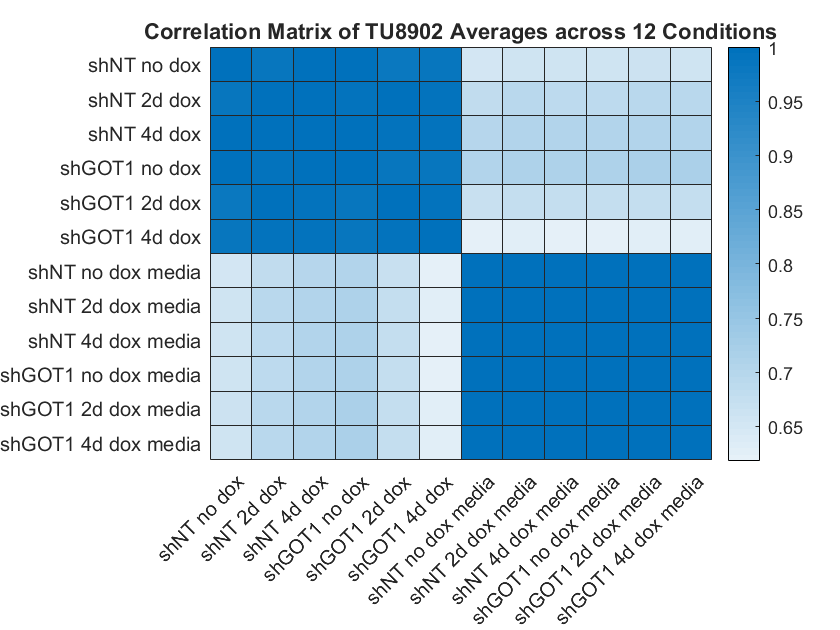

% create arrays from the tables above. 
mean_metabolomic_array_TU8902 = table2array(Tabl_average_TU8902(:,2:end));
std_metabolomic_array_TU8902 = table2array(Tabl_std_TU8902(:,2:end));

mean_metabolomic_array_HCT116 = table2array(Tabl_average_HCT116(:,2:end));
std_metabolomic_array_HCT116 = table2array(Tabl_std_HCT116(:,2:end));

%Convert all the NaN values to 0
mean_metabolomic_array_TU8902(isnan(mean_metabolomic_array_TU8902)) = 0;
mean_metabolomic_array_HCT116(isnan(mean_metabolomic_array_HCT116)) = 0;

%r matrix and its heatmap - for the 12 conditions
averageCorrMat_TU8902 = corrcoef(mean_metabolomic_array_TU8902);
figure (1);
heatmap(all_conditions, all_conditions, averageCorrMat_TU8902);
title 'Correlation Matrix of TU8902 Averages across 12 Conditions';

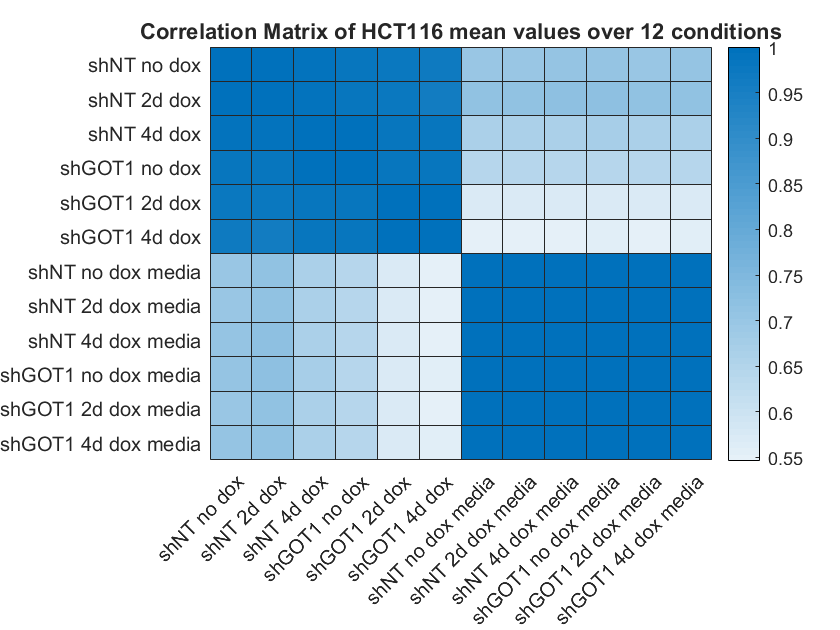


averageCorrMat_HCT116 = corrcoef(mean_metabolomic_array_HCT116);
figure (2);
heatmap(all_conditions, all_conditions, averageCorrMat_HCT116);
title 'Correlation Matrix of HCT116 mean values over 12 conditions';


% create r matrix and heatmaps for the metabolomics
corrmat = zeros(12);
for i = 1:size(mean_metabolomic_array_TU8902, 1)
    metabolite = mean_metabolomic_array_TU8902(i, :);
    tmp = corr(metabolite);
    corrmat(:, i) = diag(tmp);
end 
% NOTE: Running this gives a matrix of NaNs.

## Create the correlation matrix, CV 

%CV matrix
CV_TU8902 = std_metabolomic_array_TU8902 ./ mean_metabolomic_array_TU8902;
CV_TU8902_GOT1 = std_TU8902_GOT1 ./ avg_TU8902_GOT1;
CV_TU8902_NT = std_TU8902_NT ./ avg_TU8902_NT;

CV_HCT116 = std_metabolomic_array_HCT116 ./ mean_metabolomic_array_HCT116;
CV_HCT116_GOT1 = std_HCT116_GOT1 ./ avg_HCT116_GOT1;
CV_HCT116_NT = std_HCT116_NT ./ avg_HCT116_NT;

## Create heatmaps to visualize the averages

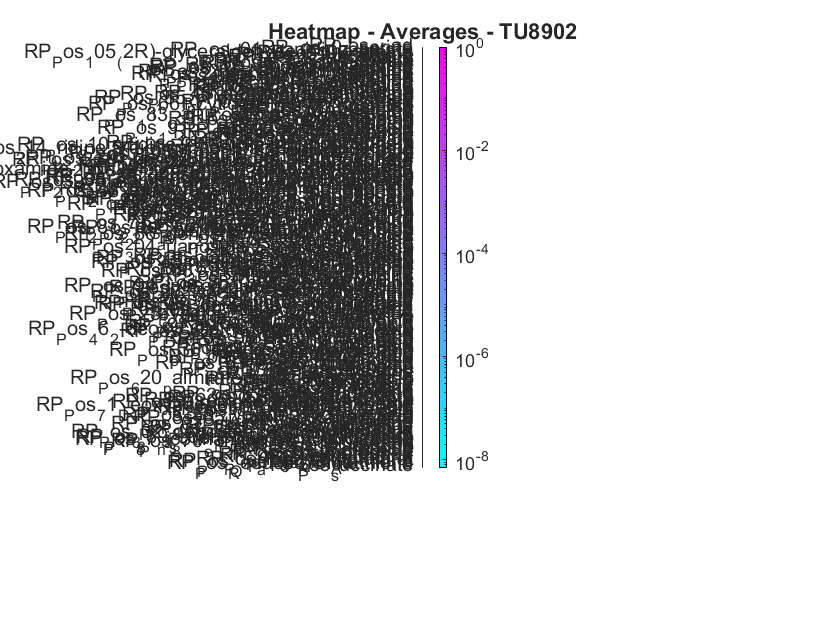

figure (3);
heatmap(all_conditions, metabolomics(:,1),mean_metabolomic_array_TU8902, 'ColorScaling', 'log');
xlabel('Conditions');
ylabel('Metabolite');
title('Heatmap - Averages - TU8902');
colormap 'cool';

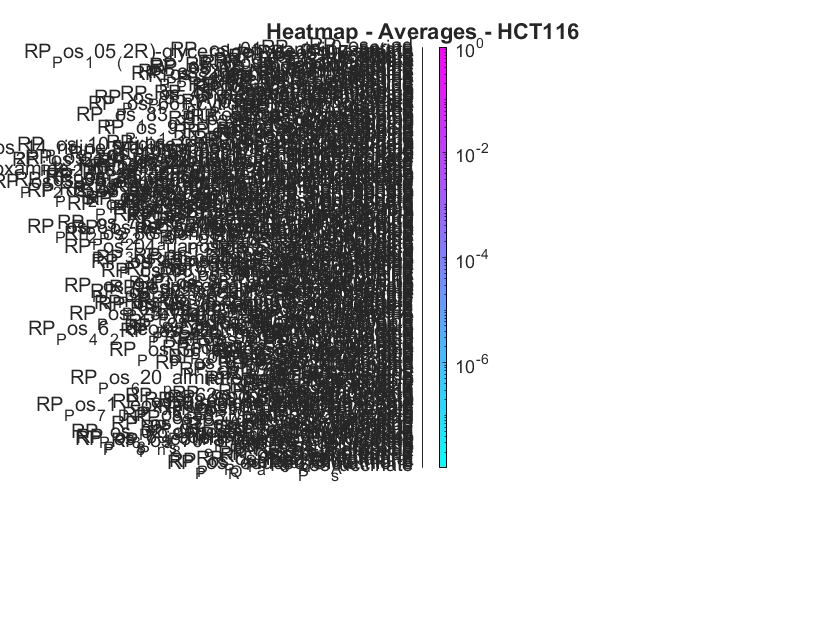

figure (4);
heatmap(all_conditions, metabolomics(:,1),mean_metabolomic_array_HCT116, 'ColorScaling', 'log');
xlabel('Conditions');
ylabel('Metabolite');
title('Heatmap - Averages - HCT116');
colormap 'cool';

## Scatterplots of the mean and standard deviations

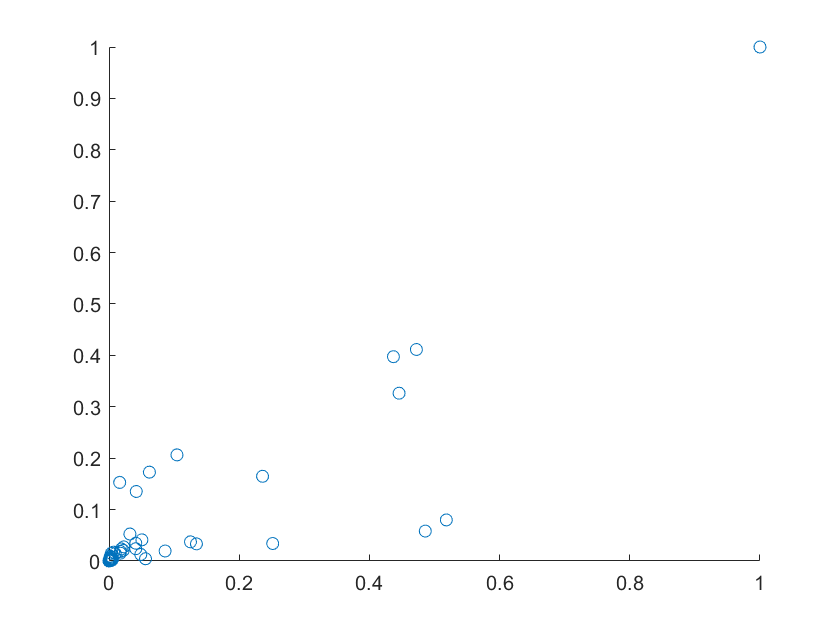

%scatterplots of mean and std
figure (5);
scatter(mean_metabolomic_array_TU8902(:,1), std_metabolomic_array_TU8902(:,1));

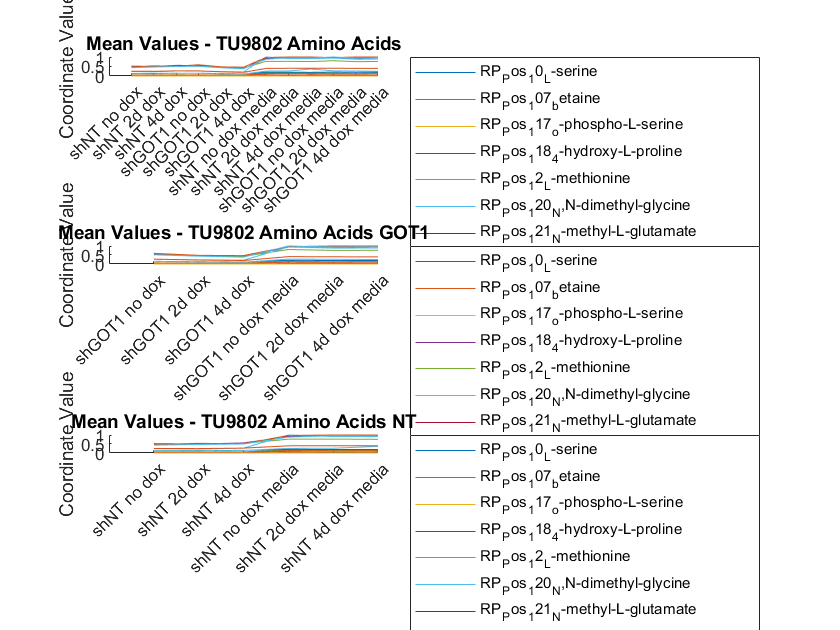

figure (6);

aminoAcidIndex = findClusterType(metabolomics,'amino acid');
subplot(3,1,1);
parallelcoords(mean_metabolomic_array_TU8902(aminoAcidIndex,:), 'group', metabolomics(aminoAcidIndex,1), 'Labels', all_conditions);
xtickangle(45);
title('Mean Values - TU9802 Amino Acids')
legend('location', 'bestoutside');
subplot(3,1,2);
parallelcoords(avg_TU8902_GOT1(aminoAcidIndex,:), 'group', metabolomics(aminoAcidIndex,1), 'Labels', got1_conditions);
xtickangle(45);
title('Mean Values - TU9802 Amino Acids GOT1')
legend('location', 'bestoutside');

subplot(3,1,3);
parallelcoords(avg_TU8902_NT(aminoAcidIndex,:), 'group', metabolomics(aminoAcidIndex,1), 'Labels', nt_conditions);
xtickangle(45);
title('Mean Values - TU9802 Amino Acids NT')
legend('location', 'bestoutside');

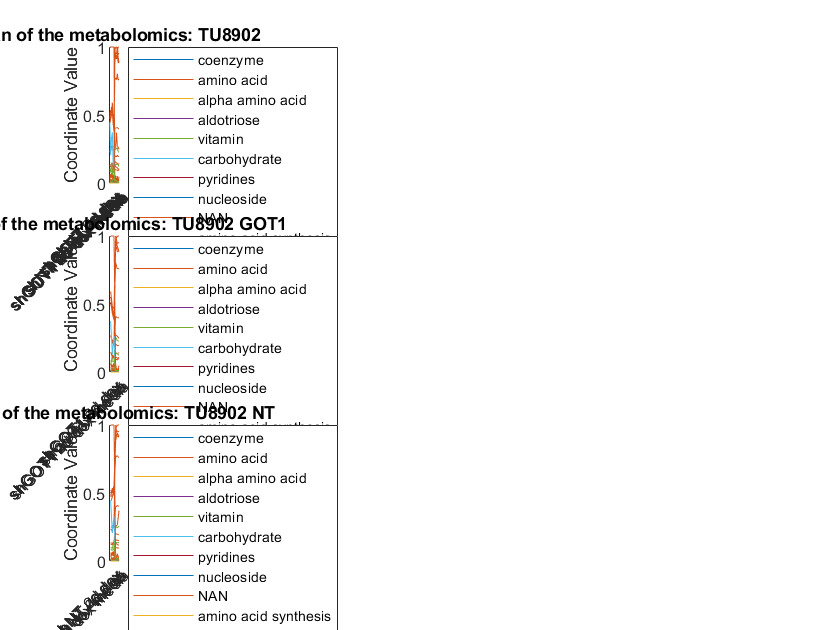


figure (7);
hold on

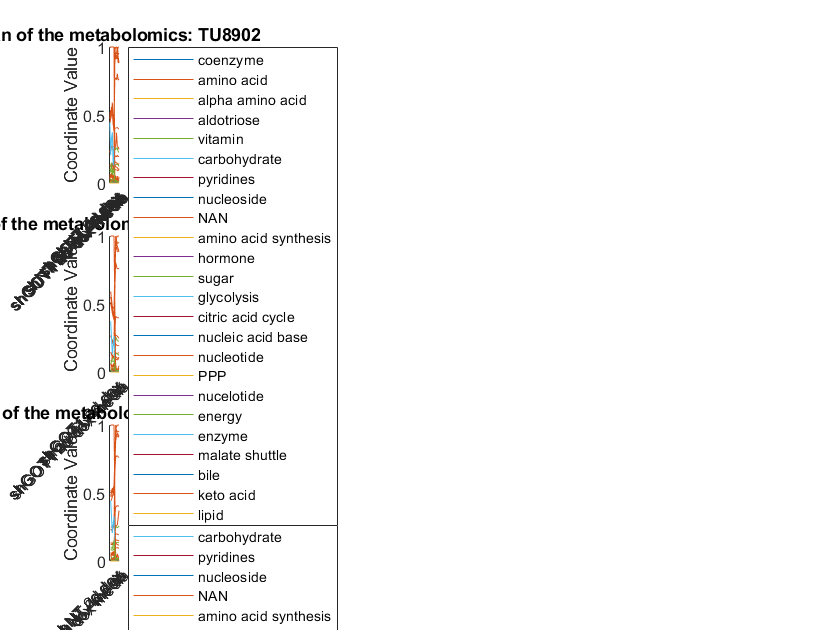

subplot(3,1,1);
parallelcoords(mean_metabolomic_array_TU8902, 'group', metabolomics(:,2), 'labels', all_conditions);
xtickangle(45);
title('Mean of the metabolomics: TU8902');
legend('location', 'bestoutside');

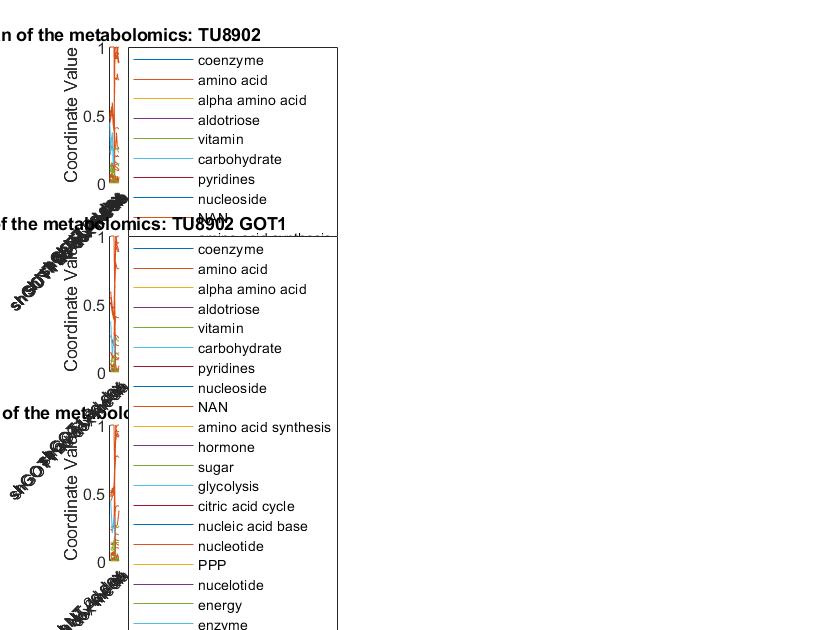


subplot(3,1,2);
parallelcoords(avg_TU8902_GOT1, 'group', metabolomics(:,2), 'labels', got1_conditions);
xtickangle(45);
title('Mean of the metabolomics: TU8902 GOT1');
legend('location', 'bestoutside');


subplot(3,1,3);
parallelcoords(avg_TU8902_NT, 'group', metabolomics(:,2), 'labels', nt_conditions);
xtickangle(45);
title('Mean of the metabolomics: TU8902 NT');
legend('location', 'bestoutside');
hold off

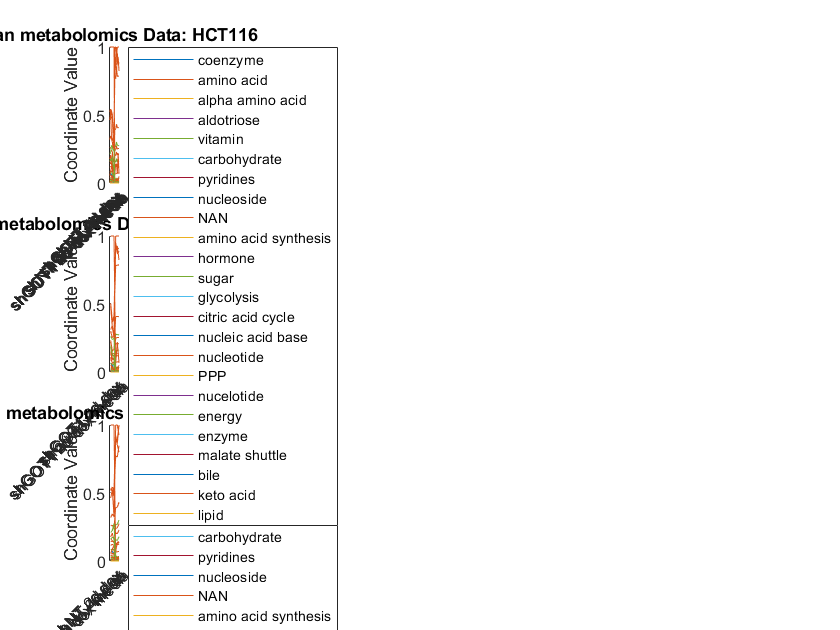


figure (8)

subplot(3,1,1);
parallelcoords(mean_metabolomic_array_HCT116, 'group', metabolomics(:,2), 'Labels', all_conditions);
xtickangle(45);
title('Mean metabolomics Data: HCT116');
legend('location', 'bestoutside');

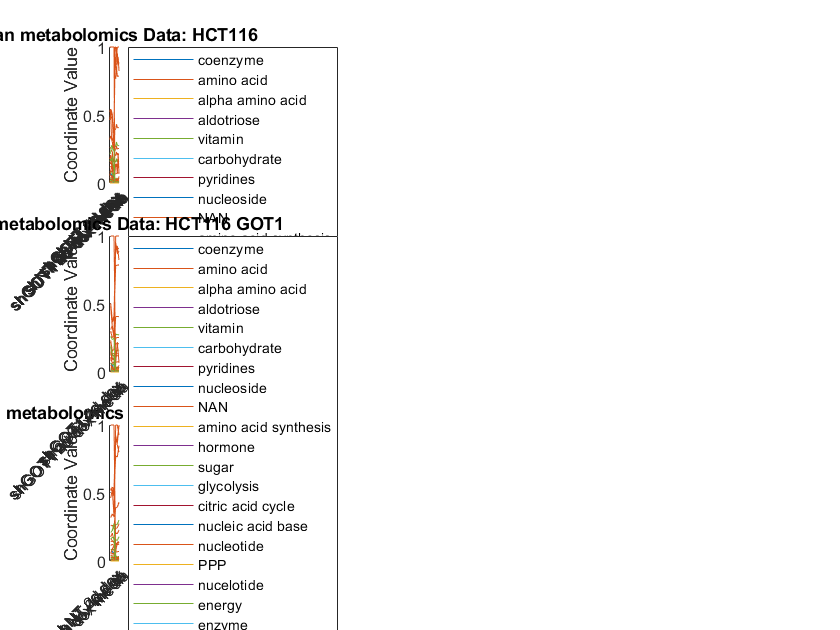


subplot(3,1,2);
parallelcoords(avg_HCT116_GOT1, 'group', metabolomics(:,2), 'Labels', got1_conditions);
xtickangle(45);
title('Mean metabolomics Data: HCT116 GOT1');
legend('location', 'bestoutside');

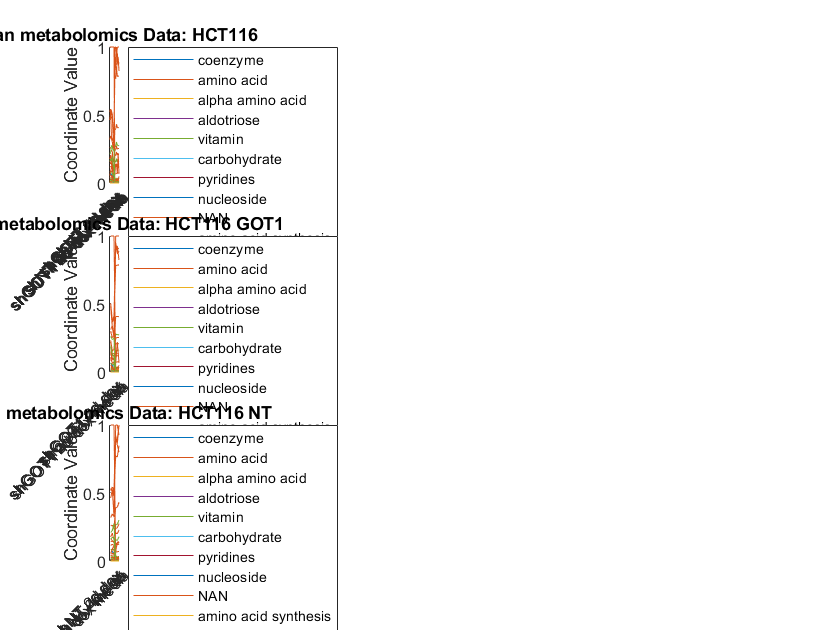


subplot(3,1,3);
parallelcoords(avg_HCT116_NT, 'group', metabolomics(:,2), 'Labels', nt_conditions);
xtickangle(45);
title('Mean metabolomics Data: HCT116 NT');
legend('location', 'bestoutside');
hold off

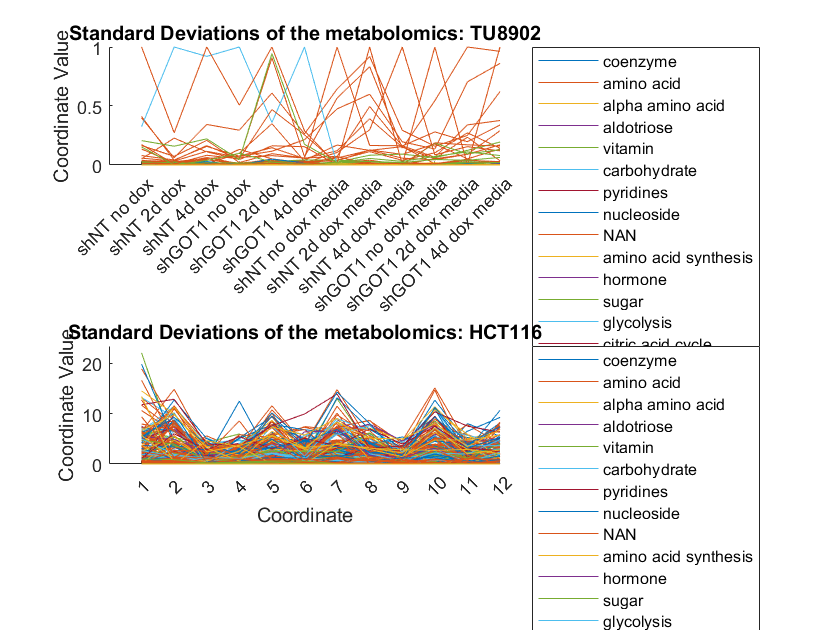


figure (9);
hold on
subplot(2,1,1);
parallelcoords(std_metabolomic_array_TU8902, 'group', metabolomics(:,2), "Labels", all_conditions);
xtickangle(45);
title('Standard Deviations of the metabolomics: TU8902');
legend('location', 'bestoutside');

subplot(2,1,2);
parallelcoords(std_metabolomic_array_HCT116, 'group', metabolomics(:,2), 'Labels', all_conditions);
xtickangle(45);
title('Standard Deviations of the metabolomics: HCT116');
legend('location', 'bestoutside');
hold off

## Coefficient of Variation Plots

This is a high level plot of the CV. 

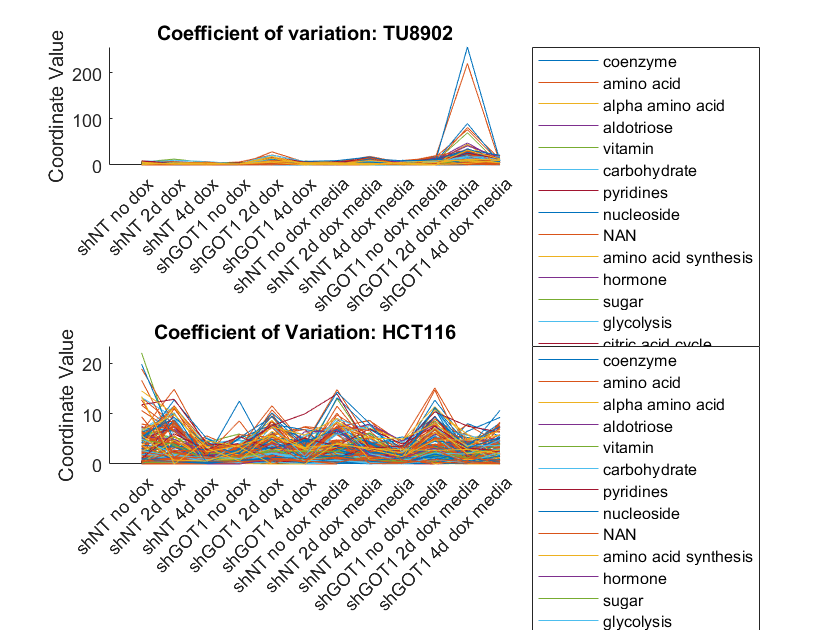

figure (10);
subplot(2,1,1);
parallelcoords(CV_TU8902, 'group', metabolomics(:,2), 'Labels', all_conditions);
xtickangle(45);
title('Coefficient of variation: TU8902');
legend('location', 'bestoutside');

subplot(2,1,2);
parallelcoords(CV_HCT116, 'group', metabolomics(:,2), 'Labels', all_conditions);
xtickangle(45);
title('Coefficient of Variation: HCT116');
legend('location', 'bestoutside');

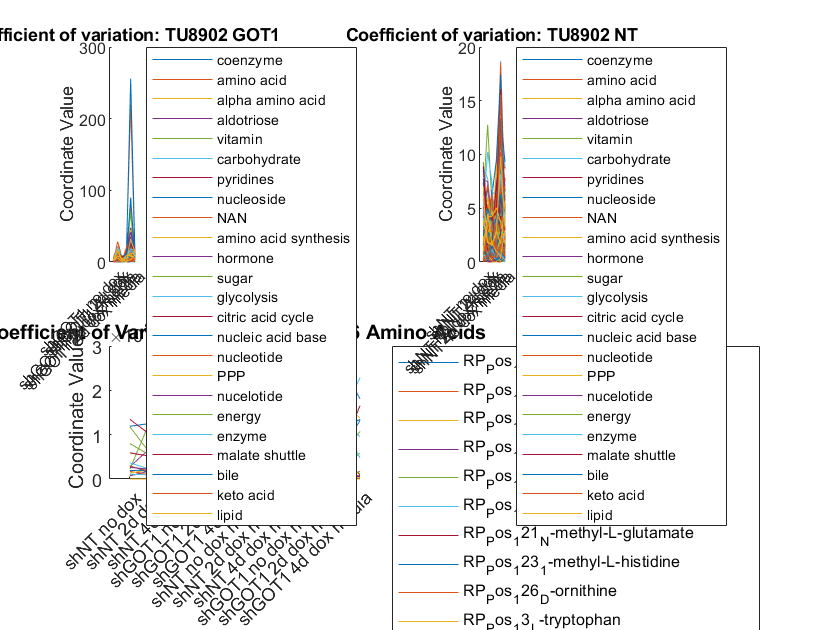


figure (11);
subplot(2,2,1);
parallelcoords(CV_TU8902_GOT1, 'group', metabolomics(:,2), 'Labels', got1_conditions);
xtickangle(45);
title('Coefficient of variation: TU8902 GOT1');
legend('location', 'bestoutside');

subplot(2,2,2);
parallelcoords(CV_TU8902_NT, 'group', metabolomics(:,2), 'Labels', nt_conditions);
xtickangle(45);
title('Coefficient of variation: TU8902 NT');
legend('location', 'bestoutside');

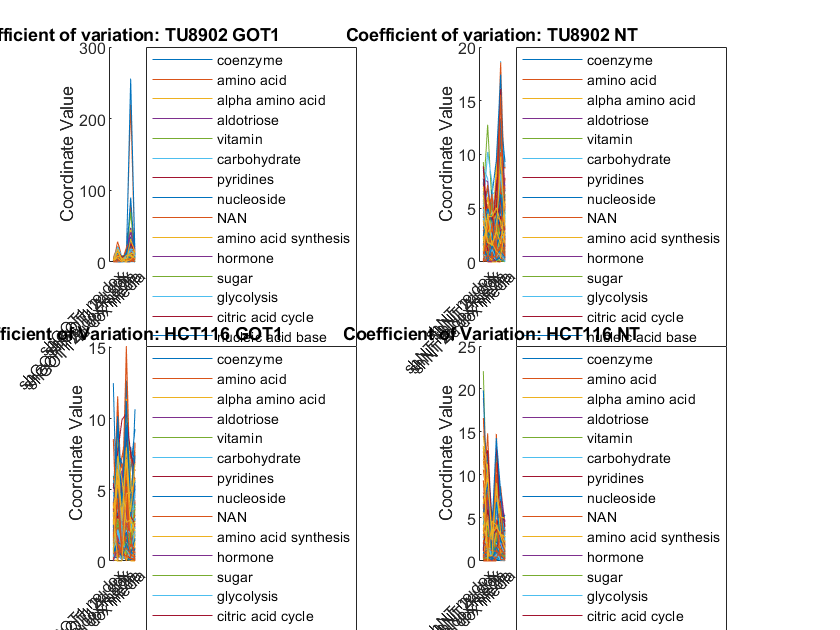


subplot(2,2,3);
parallelcoords(CV_HCT116_GOT1, 'group', metabolomics(:,2), 'Labels', got1_conditions);
xtickangle(45);
title('Coefficient of Variation: HCT116 GOT1');
legend('location', 'bestoutside');

subplot(2,2,4);
parallelcoords(CV_HCT116_NT, 'group', metabolomics(:,2), 'Labels', nt_conditions);
xtickangle(45);
title('Coefficient of Variation: HCT116 NT');
legend('location', 'bestoutside');

Now we will look specifically at the amino acids.

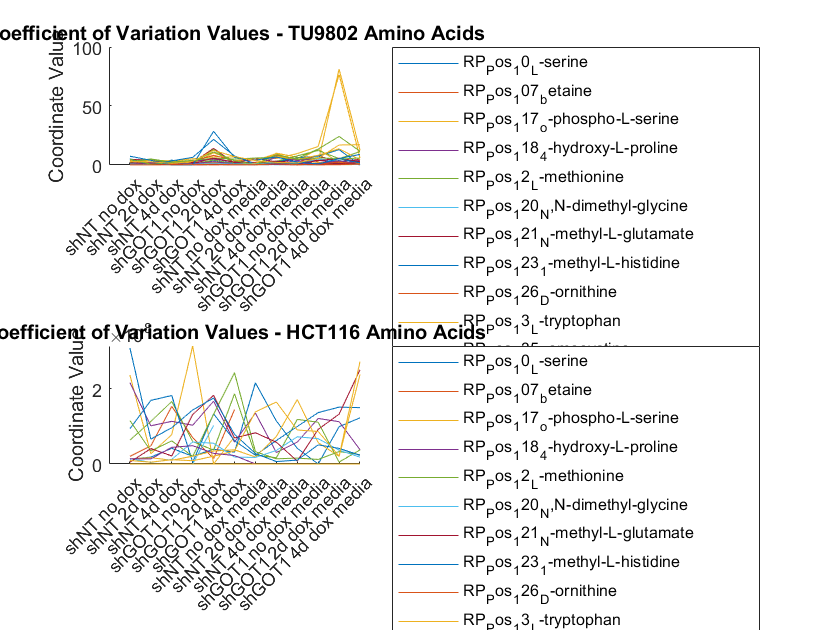

figure (12);
hold on
subplot(2,1,1);
parallelcoords(CV_TU8902(aminoAcidIndex,:), 'group', metabolomics(aminoAcidIndex,1), 'Labels', all_conditions);
xtickangle(45);
title('Coefficient of Variation Values - TU9802 Amino Acids')
legend('location', 'bestoutside');

subplot(2,1,2);
parallelcoords(CV_HCT116(aminoAcidIndex,:), 'group', metabolomics(aminoAcidIndex,1), 'Labels', all_conditions);
xtickangle(45);
title('Coefficient of Variation Values - HCT116 Amino Acids')
legend('location', 'bestoutside');
hold off

Now we will look at nucleosides

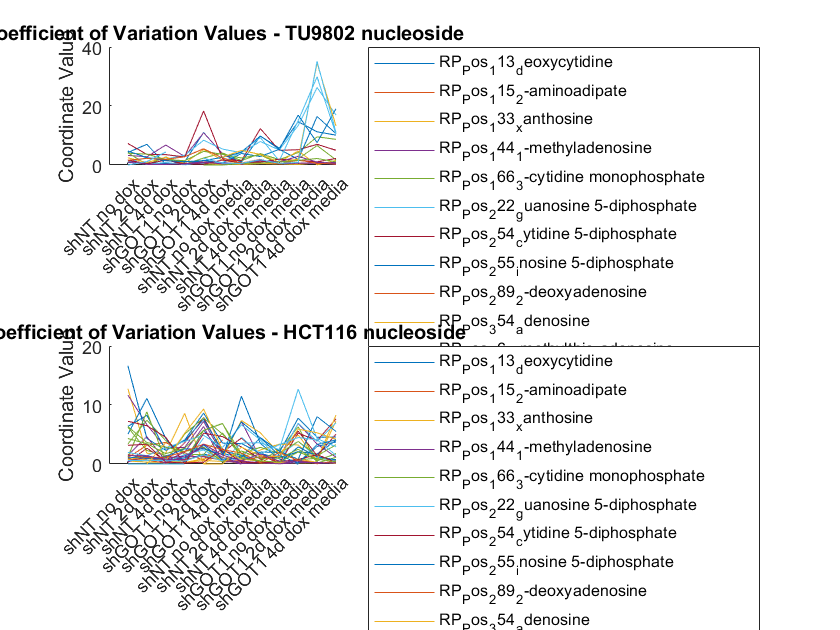

nucleosideIndex = findClusterType(metabolomics, 'nucleoside');

figure (13);
hold on
subplot(2,1,1);
parallelcoords(CV_TU8902(nucleosideIndex,:), 'group', metabolomics(nucleosideIndex,1), 'Labels', all_conditions);
xtickangle(45);
title('Coefficient of Variation Values - TU9802 nucleoside')
legend('location', 'bestoutside');

subplot(2,1,2);
parallelcoords(CV_HCT116(nucleosideIndex,:), 'group', metabolomics(nucleosideIndex,1), 'Labels', all_conditions);
xtickangle(45);
title('Coefficient of Variation Values - HCT116 nucleoside')
legend('location', 'bestoutside');
hold off

Now we will look at nucleotides

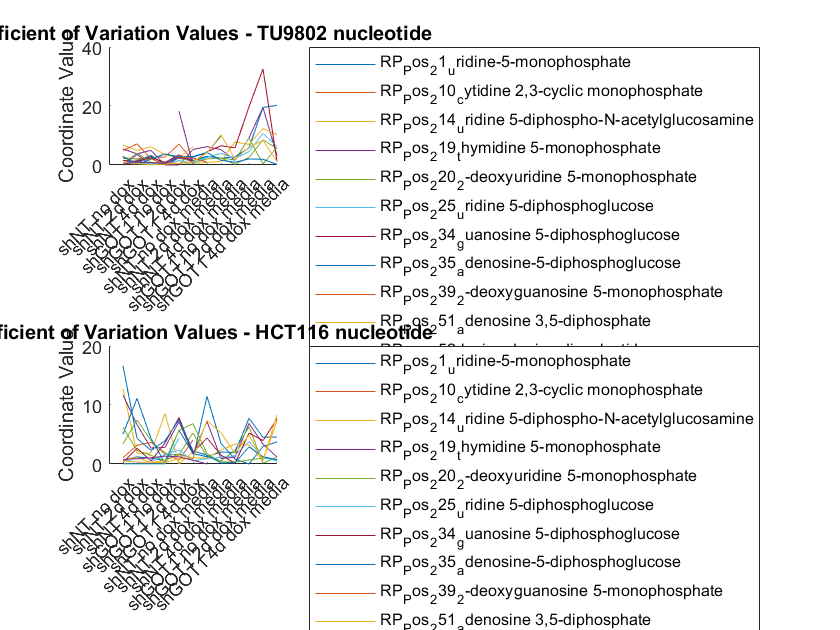

nucleotideIndex = findClusterType(metabolomics, 'nucleotide');

figure (14);
hold on
subplot(2,1,1);
parallelcoords(CV_TU8902(nucleotideIndex,:), 'group', metabolomics(nucleotideIndex,1), 'Labels', all_conditions);
xtickangle(45);
title('Coefficient of Variation Values - TU9802 nucleotide')
legend('location', 'bestoutside');

subplot(2,1,2);
parallelcoords(CV_HCT116(nucleotideIndex,:), 'group', metabolomics(nucleotideIndex,1), 'Labels', all_conditions);
xtickangle(45);
title('Coefficient of Variation Values - HCT116 nucleotide')
legend('location', 'bestoutside');
hold off

## DFA Filter 1: CV thresholds

[metabolite_keep_TU8902, metabolite_delete_TU8902] = all_CV_Filter(CV_TU8902,metabolomics,Tabl_average_TU8902,0.9);
[metabolite_keep_HCT116, metabolite_delete_HCT116] = all_CV_Filter(CV_HCT116,metabolomics,Tabl_average_HCT116,0.9); 

## DFA Filter 2: NaN metabolomics

This filter will find all of the metabolites that have no corresponding averages: no data for any of the 12 conditions. This filter will parse through the averages array and if every single column for that specific row equals 0, then the metabolite name will be added to the a new array. 

% array for TU8902 and HCT116
no_data_NAN_TU9802 = [];
no_data_NAN_HCT116 = [];
for i = 1:226
    if mean_metabolomic_array_TU8902(i,:) == 0
        no_data_NAN_TU9802 = [no_data_NAN_TU9802; metabolomics(i)];
    end
    
    if mean_metabolomic_array_HCT116(i,:) == 0
        no_data_NAN_HCT116 = [no_data_NAN_HCT116; metabolomics(i)];
    end
end

## Use Filter 2 to create new data sheet

Now, we will use the Filter 2 to create an excel sheet for DFA. 

We will first locate all the locations that have only NaN's in tables and then delete the NaN rows. The HCT116 cell line should delete 7 rows while the TU8902 cell line should delete 6 rows. 

for i = 1:219
    bool = all(isnan(table2array(Tabl_average_HCT116(i,2:end))),'all');
    if bool == true
        Tabl_average_HCT116(i, : ) = [];
    end 
end 

Repeat for the TU9802 Cell line

for i = 1:220
    bool = all(isnan(table2array(Tabl_average_TU8902(i,2:end))),'all');
    if bool == true
        Tabl_average_TU8902(i, : ) = [];
    end 
end 

Now, export the final table out as an excel sheet. 

%{
filename = 'Filter 2: HCT116 Cancer.xlsx';
writetable(Tabl_average_HCT116,filename,"FileType","spreadsheet");

filename2 = 'Filter 2: TU8902 Cancer.xlsx';
writetable(Tabl_average_TU8902,filename,"FileType","spreadsheet");
%}